clc

PatientID = 'P1'

PatientID = 'P1'

Base Diretory setup for: win
Pathways defined for use with windows
Selected channel: FCz -> 39
Selected channel: FC3 -> 38
Selected channel: C3 -> 8
Selected channel: CP3 -> 43
Selected channel: CPz -> 53
Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\irfim\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


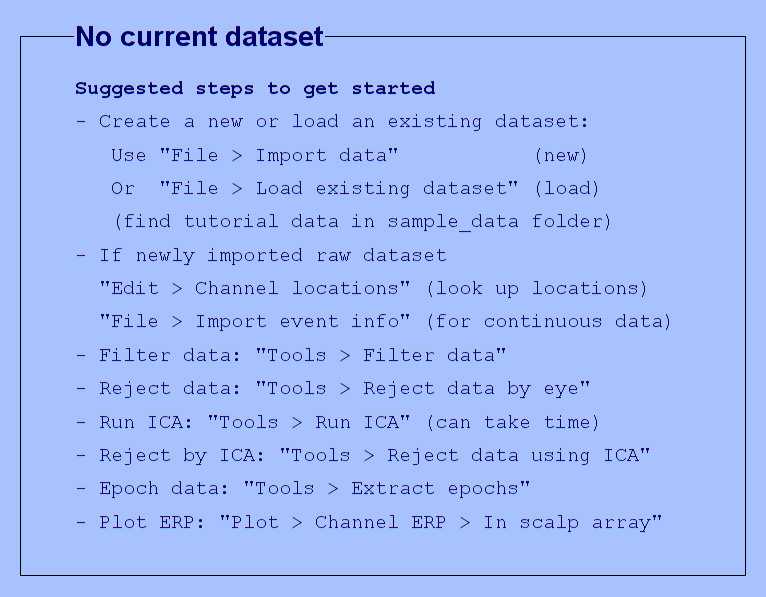

You are using the latest version of EEGLAB.
pop_loadset(): loading file C:\University\BCIWristIdentification2\OwnData\P1RH\P1RH_epochs_filt2_ICAEOG_ERDS.set ...
Reading float file 'C:\University\BCIWristIdentification2\OwnData\P1RH\P1RH_epochs_filt2_ICAEOG_ERDS.fdt'...
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 1
Removing 100 trial(s)...
Pop_select: removing 405 unreferenced events
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 2
Scaling components to RMS microvolt
channel or IC number: 1
channel or IC number: 2
channel or IC number: 3
channel or IC number: 4
channel or IC number: 5
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Scaling components to RMS m


% Define the channel pairs to be analyzed
% Original set: {'FCz-FC3','FCz-C3','FCz-CP3','Cz-FC3','Cz-C3','Cz-CP3','CPz-FC3','CPz-C3','CPz-CP3'}
% Updated set: Removed 'Cz-*' pairs for analysis
CH_pairs = {'FCz-FC3','FCz-C3','FCz-CP3','CPz-FC3','CPz-C3','CPz-CP3'};

% Select the channel pairs that are available in the dataset
% This step ensures that only valid and existing channel pairs are considered for further analysis
CH_selection = CheckChannelPairs(CH_pairs);

% Process EEG data for a specific participant
% The function 'ProcessEEGData' takes a cell array of participant IDs and the selected channel pairs as input
% Here, we process data for participant 'P1'
ProcessEEGData({PatientID}, CH_selection);


% Comment: 
% The next step involves performing calculations across multiple trials.
% For multi-trial analysis, the single-trial calculation function will be invoked within the loop.


## Prompt a user to load a .mat file containing EEG data

clc

[file, path] = uigetfile('*.mat', 'Select the MATLAB data file');
if isequal(file, 0)
    disp('User canceled the operation');
    return;
end

% Load the selected .mat file
data = load(fullfile(path, file));
disp('.mat Data File Loaded');

.mat Data File Loaded


## Multi-Trial Analysis

clc;

% Parameters for Wrist Extension (WE)
class_WE = 1;
data_WE = data.data_WE; 
WETable = MultipleTrialsIDP(data_WE, CH_pairs, CH_selection, 5000, 8000, data.times, class_WE, PatientID);

Combined results table saved to ..\OwnResults\P1RH\MatlabGeneratedData\CombinedResults_2024-08-29_12-58-15.mat



% Parameters for Wrist Flexion (WF)
class_WF = 0;
data_WF = data.data_WF; 
WFTable = MultipleTrialsIDP(data_WF, CH_pairs, CH_selection, 5000, 8000, data.times, class_WF, PatientID);

Combined results table saved to ..\OwnResults\P1RH\MatlabGeneratedData\CombinedResults_2024-08-29_12-58-17.mat



% Combine WETable and WFTable vertically to create a 200x19 table
combinedTable = [WETable; WFTable];

% Display the combined table
disp(combinedTable);

    FCz-FC3-mean    FCz-FC3-std    FCz-FC3-variance    FCz-C3-mean    FCz-C3-std    FCz-C3-variance    FCz-CP3-mean    FCz-CP3-std    FCz-CP3-variance    CPz-FC3-mean    CPz-FC3-std    CPz-FC3-variance    CPz-C3-mean    CPz-C3-std    CPz-C3-variance    CPz-CP3-mean    CPz-CP3-std    CPz-CP3-variance    Class
    ____________    ___________    ________________    ___________    __________    _______________    ____________    ___________    ________________    ____________    ___________


% Save the combined table in the appropriate directory
% Define the output directory dynamically using the patient ID
outputDir = fullfile('..', 'OwnResults', [PatientID 'RH'], 'MatlabGeneratedData');

% Create the directory if it doesn't exist
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Define the filename based on the current date and time
outputFilename = fullfile(outputDir, ['CombinedWEandWFTable_' datestr(now, 'yyyy-mm-dd_HH-MM-SS') '.mat']);

% Save the combined table to a .mat file
save(outputFilename, 'combinedTable');

% Notify the user that the data has been saved
fprintf('Combined WE and WF table saved to %s\n', outputFilename);

Combined WE and WF table saved to ..\OwnResults\P1RH\MatlabGeneratedData\CombinedWEandWFTable_2024-08-29_12-58-18.mat


## Train & Test split for data

PD = 0.70;  % Percentage for the training set (70%)

% Set a fixed random seed for reproducibility
rng(1); % Fixed seed for consistent results

% Extract the class labels from the table
labels = combinedTable.Class; % Ensure 'Class' is the actual name of your class label column

% Create a stratified partition
cv = cvpartition(labels, 'HoldOut', 1 - PD, 'Stratify', true);

% Split the data into training and test sets
Ptrain = combinedTable(training(cv), :);
Ptest = combinedTable(test(cv), :);


## Checking class distribution in the training and test split 

countWF = 0;
countWE = 0;
% Number of rows in the Ptrain table
numRows = height(Ptrain);

% Loop through each row and check the 'Class' column
for i = 1:numRows
    % Get the class value for the current row
    classValue = Ptrain.Class(i); % Make sure 'Class' is the actual column name
    
    % Perform your desired operation based on the class value
    if classValue == 1
        countWE = countWE + 1; 
    elseif classValue == 0
        % Do something for class 0
        countWF = countWF + 1; 
    else
        disp(['Unexpected class value at row ', num2str(i)]);
    end
end

countWE

countWE = 70

countWF 

countWF = 70


%Checking the test dataset
countWE = 0;
countWF = 0; 

% Number of rows in the Ptrain table
numRows = height(Ptest);

% Loop through each row and check the 'Class' column
for i = 1:numRows
    % Get the class value for the current row
    classValue = Ptest.Class(i); % Make sure 'Class' is the actual column name
    
    % Perform your desired operation based on the class value
    if classValue == 1
        countWE = countWE + 1; 
    elseif classValue == 0
        % Do something for class 0
        countWF = countWF + 1; 
    else
        disp(['Unexpected class value at row ', num2str(i)]);
    end
end

countWE

countWE = 30

countWF 

countWF = 30